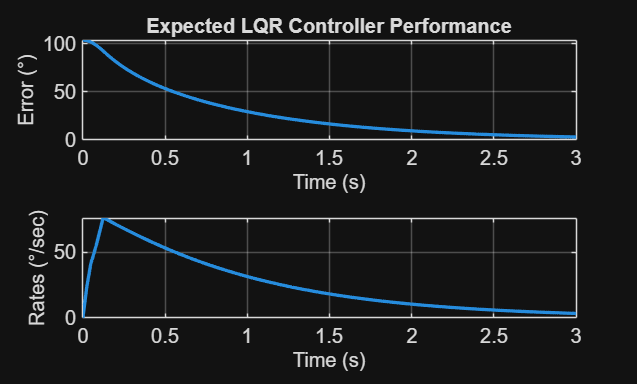

so = out.so.signals.values;
t = out.so.time;

err = so(:,1:3);
rates = so(:,4:6);
cntrls = so(:,7:9);

tiledlayout('vertical')
nexttile
plot(t,vecnorm(err,2,2),LineWidth=2)
xlim([0 3])
grid on
title('Expected LQR Controller Performance')
xlabel('Time (s)')
ylabel('Error (°)')
fontsize(12,'points')

nexttile
plot(t,vecnorm(rates,2,2),LineWidth=2)
xlim([0 3])
grid on
xlabel('Time (s)')
ylabel('Rates (°/sec)')
fontsize(12,'points')